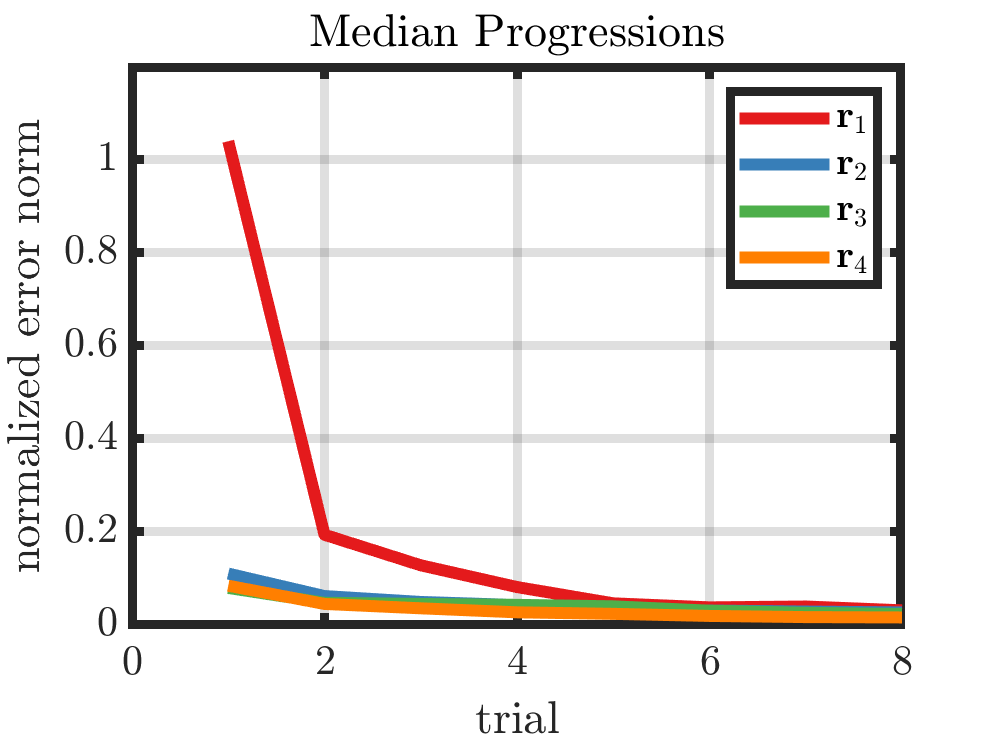

clear; close all;

% Load Data
load('2_data\results_benchmark_double_pendulum.mat');
load('2_data\benchmark_references_double_pendulum_v2.mat');

% Sizes 
W   = 5;
K   = 25;
J   = 8;

% Normalize Errors
for k = 1:K
    rck = rc(:, k);
    for w = 1:W
        ec{k}(:, w) = ec{k}(:, w)/norm(rck{w});
    end
end

% Reorder errors
ewc = cell(W, 1);
for w = 1:W
    ewc{w,1} = zeros(J, K);
end

for k = 1:K
    emat = ec{k,1};
    for w = 1:W
        ewc{w,1}(:, k) = emat(:, w);
    end
end

% Plot median error norms
c = {'#e41a1c','#377eb8','#4daf4a','#ff7f00'};
figure;
for w = 1:4
    plot(median(ewc{w,1}, 2), 'LineWidth', 4, 'Color', c{w}); hold on;
end

ylim([0, 1.2]);
legend("$\mathbf{r}_1$", "$\mathbf{r}_2$", "$\mathbf{r}_3$", "$\mathbf{r}_4$");
xlabel("trial");
ylabel("normalized error norm");
title("Median Progressions");

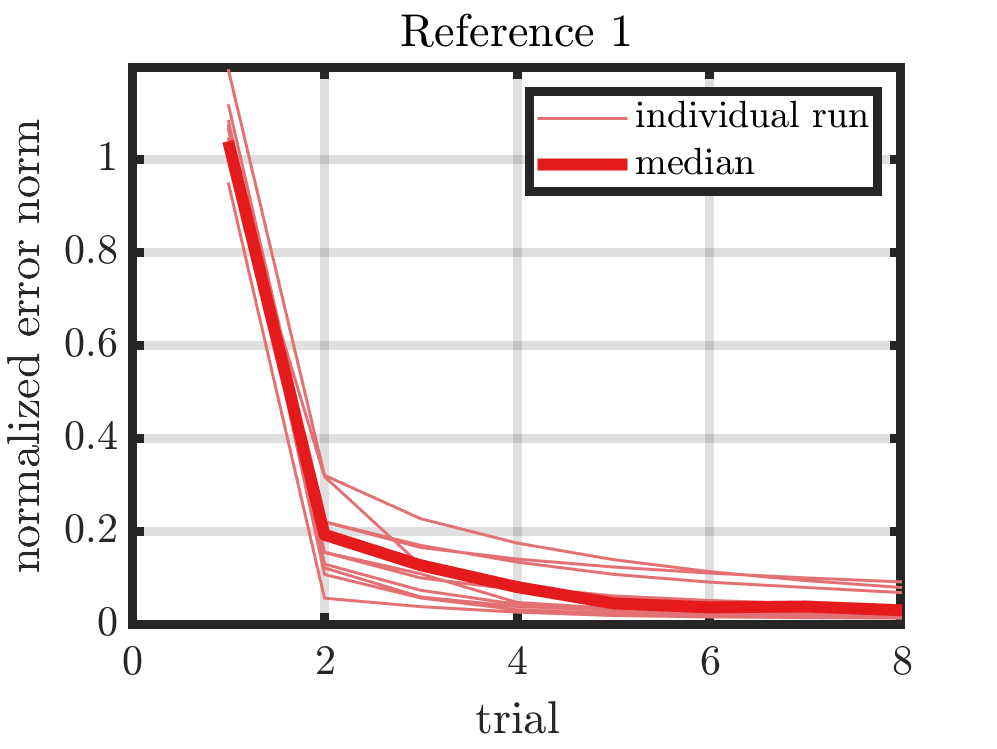


figure;
w = 1;
for k = 1:10
    l1 = plot(ewc{w,1}(:,k), 'LineWidth', 1, 'Color', "#e37173"); hold on;
end
l2 = plot(median(ewc{w,1}, 2), 'LineWidth', 4, 'Color', c{w}); hold on;
xlabel("trial");
ylabel("normalized error norm");
legend([l1, l2], {"individual run", "median"});
title("Reference 1");
ylim([0, 1.2]);

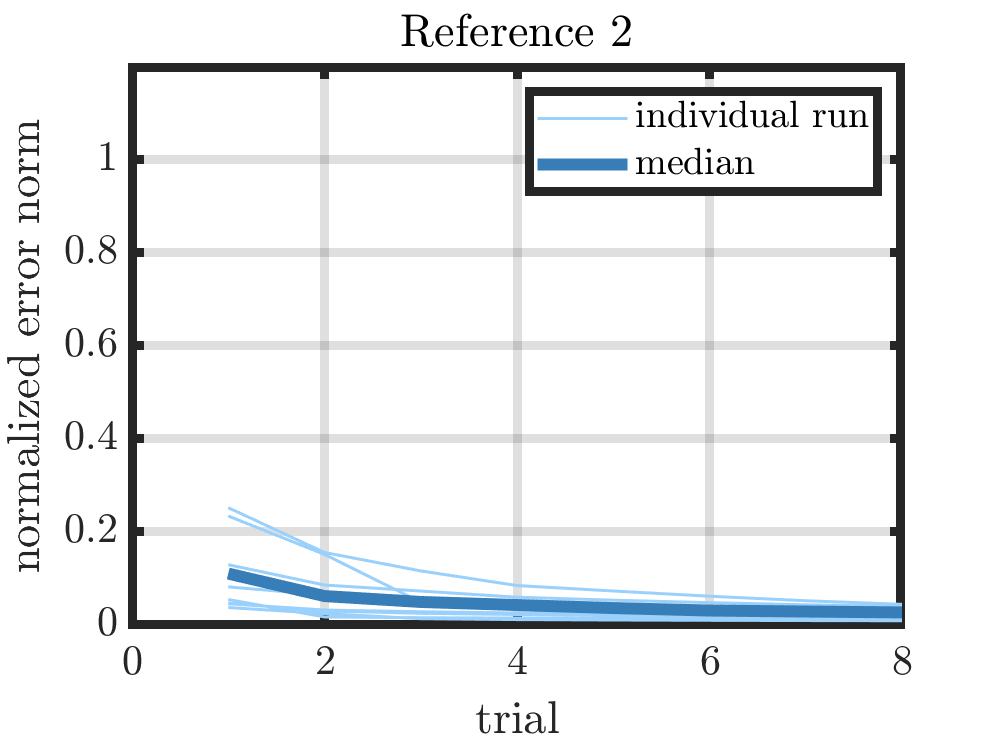


figure;
w = 2;
for k = 1:10
    l1 = plot(ewc{w,1}(:,k), 'LineWidth', 1, 'Color', "#9ad0fc"); hold on;
end
l2 = plot(median(ewc{w,1}, 2), 'LineWidth', 4, 'Color', c{w}); hold on;
xlabel("trial");
ylabel("normalized error norm");
legend([l1, l2], {"individual run", "median"});
title("Reference 2");
ylim([0, 1.2]);

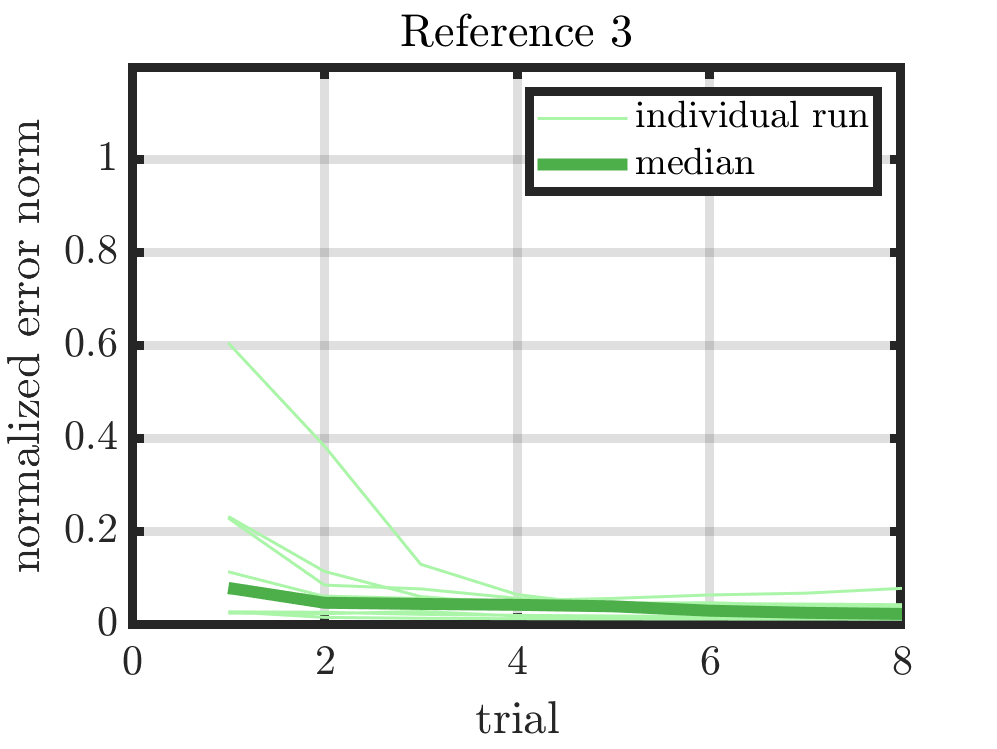


figure;
w = 3;
for k = 1:10
    l1 = plot(ewc{w,1}(:,k), 'LineWidth', 1, 'Color', "#abf5a9"); hold on;
end
l2 = plot(median(ewc{w,1}, 2), 'LineWidth', 4, 'Color', c{w}); hold on;
xlabel("trial");
ylabel("normalized error norm");
legend([l1, l2], {"individual run", "median"});
title("Reference 3");
ylim([0, 1.2]);

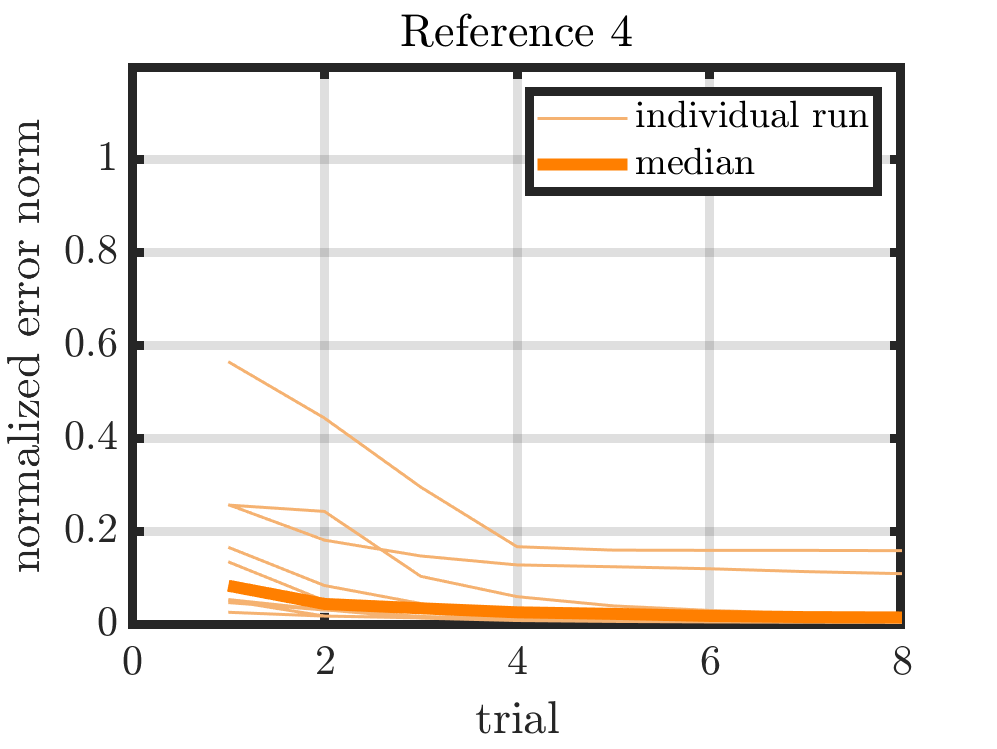


figure;
w = 4;
for k = 1:10
    l1 = plot(ewc{w,1}(:,k), 'LineWidth', 1, 'Color', "#f5b271"); hold on;
end
l2 = plot(median(ewc{w,1}, 2), 'LineWidth', 4, 'Color', c{w}); hold on;
xlabel("trial");
ylabel("normalized error norm");
legend([l1, l2], {"individual run", "median"});
title("Reference 4");
ylim([0, 1.2]);